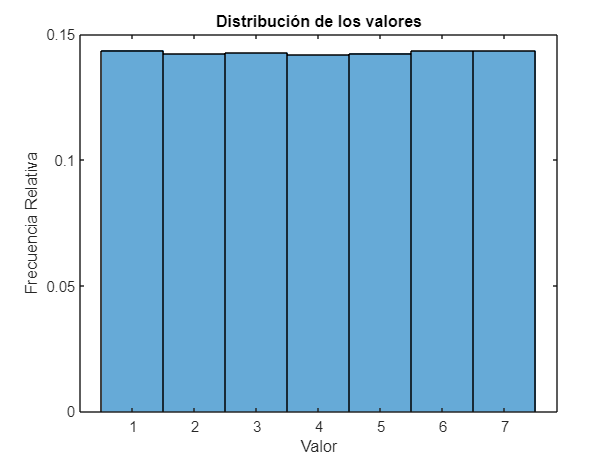

clear
for j = 1:100000
    value(j)= randomNum7();
end
figure;
histogram(value, 'BinEdges', 0.5:1:7.5, 'Normalization', 'probability');
title('Distribución de los valores');
xlabel('Valor');
ylabel('Frecuencia Relativa');

function [outputArg1] = randomNum5()
outputArg1 = randi([1 5]);
end
function [result]= randomNum7()
    i = 5*randomNum5() + randomNum5() - 5;
    if (i < 22)
        result = mod(i,7) + 1;
    else
        result = randomNum7();
    end
end